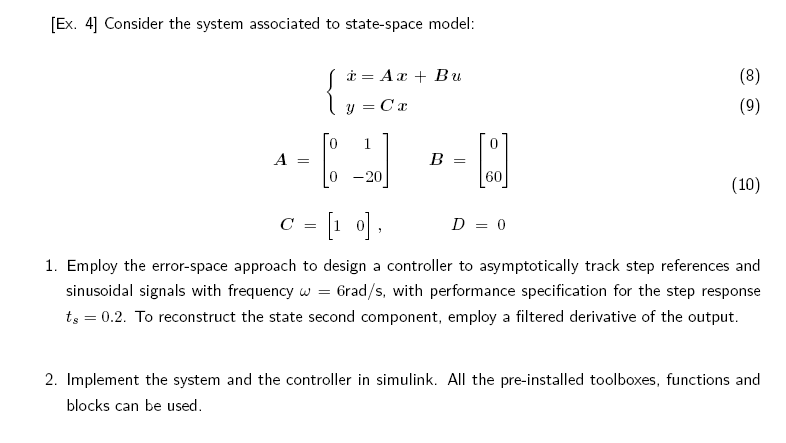

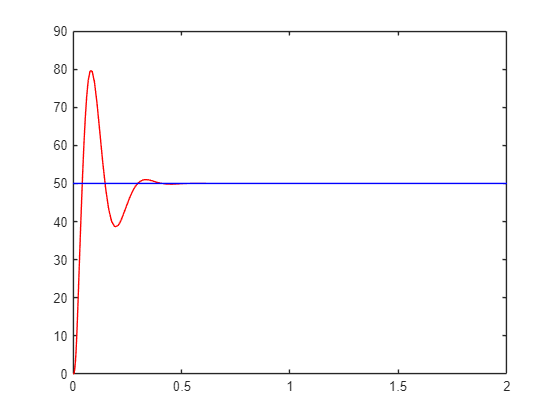

clear all
clc

% 1) Define specifications & dominant pole approximation

ts = 0.2;
omega_0 = 6; % rad/s

% ts = 4.6/sigma < 0.2;

% sigma >4.6/0.2 = 23;

sigma = 4.6/0.2; % sigma = delta * omega_n

% i choose delta_1 = 0.707 and delta_2 = 0.866. I need to consider the dominant pole (slower pole)
% i need delta_1 * omega_n > 23. so 

omega_n_min = sigma/0.707;

% I choose omega_n = 35;

omega_n = 35;

% Define Plant and  Exosystem

A = [ 0, 1; 0, -20];
B = [0 ; 60];
C = [1, 0];
D = 0;

A_r = [ 0 1 0; 0 0 1; 0 -(omega_0^2) 0];

% Define Error-Space Augmented System 

A_e = [A_r,[zeros(2,2);C];zeros(2,3),A];

B_e = [zeros(3,1);B];

% 5 Pole Placement
p1 = omega_n * exp(1j * (-pi + pi/4));
p2 = conj(p1);
p3 = omega_n * exp(1j * (-pi + pi/6));
p4 = conj(p3);
p5 = -omega_n;
e_poles = [p1, p2, p3, p4, p5];

% Compute the augmented gain vector

k_e = place(A_e,B_e,e_poles);

% Considering the control law u = -k_xi * x - H(s)*e
% Define H(s) as part of vector k_e 
numH = flip(k_e(1:3));
denH = [1, 0, omega_0^2, 0];

% Compute K_xi gain as part of vector k_e
K_xi = k_e(4:5); 

% Compute derivative filter

omega_filter = 2*50*pi;

delta_filter = 1/sqrt(2);

num_filter = [omega_filter^2 0];
den_filter = [1 2*delta_filter*omega_filter omega_filter^2];

% step response

input_value = 1;

step_amplitude = 50;

data = sim('ex_4_sim.slx');

t = data.ScopeData.time;
tetha = data.ScopeData.signals(1).values;
input_step = data.ScopeData.signals(2).values ;
figure;
plot(t,tetha,'r')
hold on
plot(t,input_step,'b')
axis([0 2 0 90])
hold off

step_data = stepinfo(tetha,t,50,"SettlingTimeThreshold",0.01);
disp(step_data);

         RiseTime: 0.0263
    TransientTime: 0.3758
     SettlingTime: 0.3758
      SettlingMin: 38.6284
      SettlingMax: 79.5551
        Overshoot: 59.1101
       Undershoot: 0
             Peak: 79.5551
         PeakTime: 0.0788



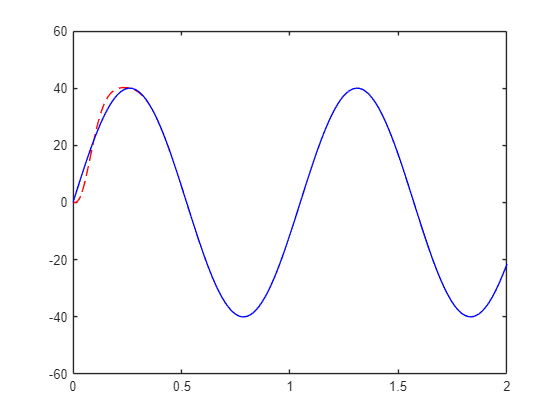

% sine response

input_value = 2;

data = sim('ex_4_sim.slx');

t = data.ScopeData.time;
tetha = data.ScopeData.signals(1).values;
input_step = data.ScopeData.signals(2).values ;
figure;
plot(t,tetha,'r--')
hold on
plot(t,input_step,'b-')
axis([0 2 -60 60])
hold off